### **Creating a Transfer Matrix Given Number of States**

Using a while loop and if-else statements

Inputs: lenL = # of states in L, lenR = # of states in R. These values represent the length of the index sets of L and R.

The transfer matrix will be a square matrix regardless of the number of states in L and R. For example, if there are 3 states in L and 4 states in R then there will be 7 rows and 7 columns.

The function transferMatrix rearrages a [L1 L2 L3 ... R1 R2 R3 ...] to [L1 R1 L2 R2 L3 R3 ...]. 

idx_set_L = randi(4,[6,1]);
idx_set_R = randi(4,[6,1]);
tempMat = transferMatrix(idx_set_L, idx_set_R)

### **Deriving A, B, and C from the realization of L**

For example, if there is a matrix L as below

|L_11 0 L_13|

|0    L_22   0 |

|0      0  L_33|

then we want to derive each L's A,B,C,D by each column of the matrix of Ls so that we can create a global matrix of each A, B, C, D which we can use to come up with a global realization of L.

clear; clc

%transfer matrix with the structure adjacency = [ 1,0,1; 0,1,0; 0,0,1 ].
%The actual values of the nonzero elements are irrelevant here; just their
%placement matters

% mat = [1 2; 4 6; 7 3; 56 78]
% size(mat, 1) % # of rows
% size(mat, 2) % # of cols

den = [1,2,1];

Phi_11 = tf([1,1],den); Phi_13 = tf([1,0],den); Phi_22 = tf(1,den); Phi_33 = tf([1,1],den);

Phi = [Phi_11,0,Phi_13;
    0,Phi_22,0;
    0,0,Phi_33];



output = globalRealization(Phi)
LTI_equiv(Phi, output)
spsty_idx_set(output.C, [1 1 1], [2 2 2])

## Generating an Arbitrary Realization to Transform

We have found that for realizations

one realization of  is given by

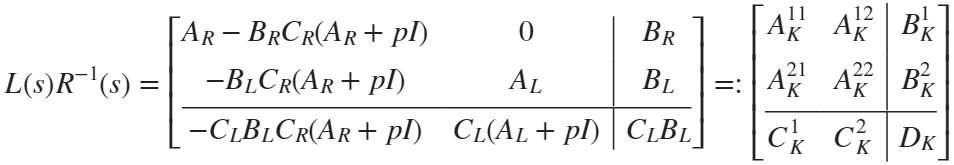

where *p* is some arbitrary scalar.

%create some random realizations of R and L that have the proper structure
%and index sets
idx_set_L = randi(4,[3,1]);
idx_set_R = randi(4,[3,1]);

adjacency = [1,1,1;
            0,1,1;
            0,0,1]; %structure

p = 1;

[AK, BK, CK, DK] = generateRealization(p, idx_set_L, idx_set_R, adjacency)